# What Kind of Flower is That?

This example uses transfer learning to train a deep network that can classify images of flowers into one of 12 species.

## Get training images

flowerds = imageDatastore("Flowers","IncludeSubfolders",true,"LabelSource","foldernames");

Split into training and testing sets

[trainImgs,testImgs] = splitEachLabel(flowerds,0.6);

Determine the number of flower species

numClasses = numel(categories(flowerds.Labels));

## Create a network by modifying GoogLeNet

Get the layers from GoogLeNet

net = googlenet;
lgraph = layerGraph(net)

lgraph =   LayerGraph with properties:

         Layers: [144×1 nnet.cnn.layer.Layer]
    Connections: [170×2 table]
     InputNames: {'data'}
    OutputNames: {'output'}


Modify the classification and output layers

newFc = fullyConnectedLayer(12,"Name","new_fc")

newFc =   FullyConnectedLayer with properties:

          Name: 'new_fc'

   Hyperparameters
     InputSize: 'auto'
    OutputSize: 12

   Learnable Parameters
       Weights: []
          Bias: []

  Show all properties


lgraph = replaceLayer(lgraph,"loss3-classifier",newFc)

lgraph =   LayerGraph with properties:

         Layers: [144×1 nnet.cnn.layer.Layer]
    Connections: [170×2 table]
     InputNames: {'data'}
    OutputNames: {'output'}


newOut = classificationLayer("Name","new_out")

newOut =   ClassificationOutputLayer with properties:

            Name: 'new_out'
         Classes: 'auto'
      OutputSize: 'auto'

   Hyperparameters
    LossFunction: 'crossentropyex'


lgraph = replaceLayer(lgraph,"output",newOut)

lgraph =   LayerGraph with properties:

         Layers: [144×1 nnet.cnn.layer.Layer]
    Connections: [170×2 table]
     InputNames: {'data'}
    OutputNames: {'new_out'}


## Set training algorithm options

Lower the learning rate for transfer learning

options = trainingOptions("sgdm","InitialLearnRate", 0.001);

## Perform training

[flowernet,info] = trainNetwork(trainImgs, lgraph, options);

Training on single GPU.
Initializing input data normalization.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:02 |        7.03% |       4.6878 |          0.0010 |
|      13 |          50 |       00:00:44 |       96.88% |       0.0968 |          0.0010 |
|      25 |         100 |       00:01:27 |      100.00% |       0.0167 |          0.0010 |
|      30 |         120 |       00:01:45 |       98.44% |       0.0352 |          0.0010 |
|========================================================================================|


## Use the trained network to classify test images

testpreds = classify(flowernet,testImgs);

## Evaluate the results

Calculate the accuracy

nnz(testpreds == testImgs.Labels)/numel(testpreds)

ans = 0.9141

Visualize the confusion matrix

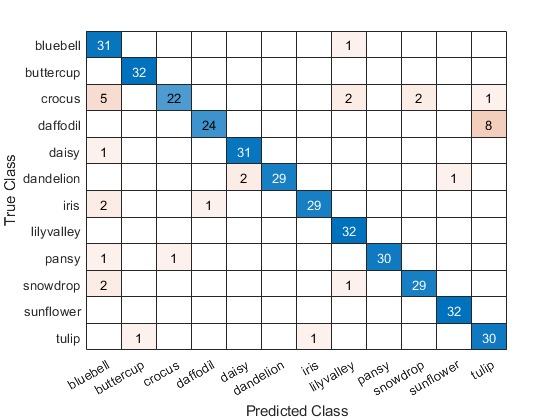

confusionchart(testImgs.Labels,testpreds);